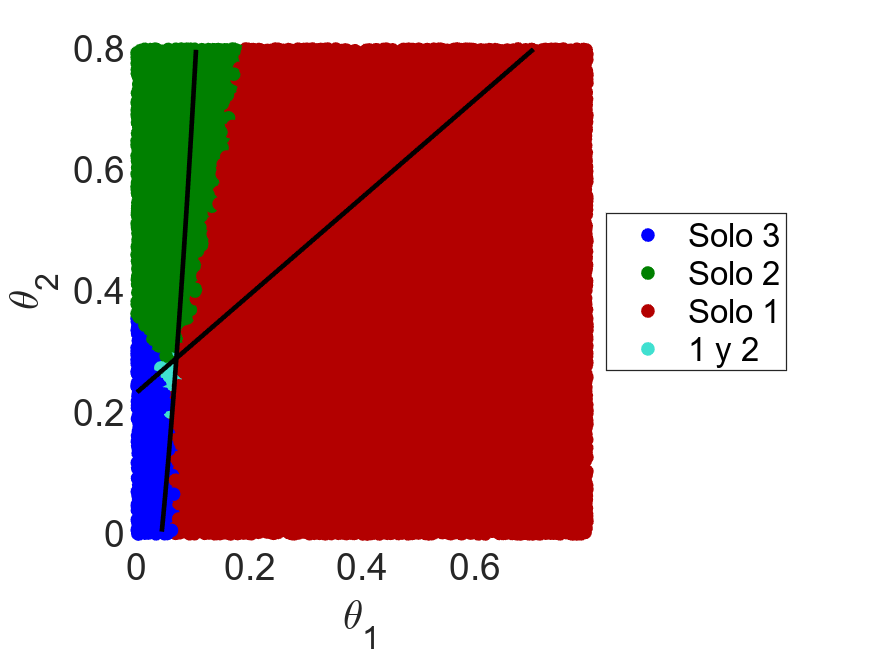

% Limpiar todo
clear;
clc;
close all;

% --- Parámetros del sistema ---
alpha1 = 0.00137; beta1 = 0.07;   gamma1 = 0.01; mu1 = 0.01;
alpha2 = 0.0011;  beta2 = 0.29;   gamma2 = 0.01; mu2 = 0.01;
alpha3 = 0.001;   beta3 = 0.1;
tau = 0.0995;
C = 146.9;

% Condición inicial
x0 = [15.4667; 0.0790; 8.9326];

% Tiempo de simulación
tspan = [0 1000];

% Número de muestras
N = 50000;

% Muestreo tipo hipercubo latino
theta_samples = 0.8 * lhsdesign(N, 2);  % ahora en [0, 0.8]
theta_samples = round(theta_samples, 4);  % redondear solo para visualización

% Crear figura
figure;
hold on;

% Umbral para determinar "cercanía a cero"
tol = 0.00001;

% Crear un mapa de colores y etiquetas para cada caso
colores = {
    [0 0 0], 'Extinción total'; % Negro
    [0 0 1], 'Solo 3'; % Azul
    [0 0.5 0], 'Solo 2'; % Verde
    [0.5 0.25 0], '2 y 3'; % Marrón
    [0.7 0 0], 'Solo 1'; % Rojo
    [1 0 1], '1 y 3'; % Amarillo
    [0.251 0.878 0.816], '1 y 2'; % Turqueza
    [1 0.5 0], 'Coexistencia total' % Naranja
};

% Crear contenedor para handles de la leyenda
handles = gobjects(size(colores,1), 1);
colores_usados = false(size(colores,1), 1);  % para llevar registro

% Simulación por cada par (theta1, theta2)
for i = 1:N
    theta1 = theta_samples(i,1);
    theta2 = theta_samples(i,2);

    % Sistema dinámico
    sistema = @(t, x) [
        (alpha1 * x(1) * (C - x(1) - x(2) - x(3))) / (1 + gamma1 * x(3)) ...
            - x(1) * (beta1 + mu1 * x(3) - theta1); 
        (alpha2 * x(2) * (C - x(1) - x(2) - x(3)) * (1 + tau * x(1))) / (1 + gamma2 * x(3)) ...
            - x(2) * (beta2 + mu2 * x(3) - theta2);
        alpha3 * x(3) * (C - x(1) - x(2) - x(3)) - beta3 * x(3)
    ];

    % Resolver sistema
    [~, x] = ode45(sistema, tspan, x0);

    % Valor final
    xf = x(end,:);
    x1vivo = xf(1) > tol;
    x2vivo = xf(2) > tol;
    x3vivo = xf(3) > tol;

    % Clasificación
    if ~x1vivo && ~x2vivo && ~x3vivo
        idx = 1;
    elseif ~x1vivo && ~x2vivo && x3vivo
        idx = 2;
    elseif ~x1vivo && x2vivo && ~x3vivo
        idx = 3;
    elseif ~x1vivo && x2vivo && x3vivo
        idx = 4;
    elseif x1vivo && ~x2vivo && ~x3vivo
        idx = 5;
    elseif x1vivo && ~x2vivo && x3vivo
        idx = 6;
    elseif x1vivo && x2vivo && ~x3vivo
        idx = 7;
    elseif x1vivo && x2vivo && x3vivo
        idx = 8;
    else
        idx = NaN;
    end

    if ~isnan(idx)
        color = colores{idx, 1};
        % Graficar y guardar handle solo una vez por color
        if ~colores_usados(idx)
            handles(idx) = plot(theta1, theta2, '.', 'Color', color, 'MarkerSize', 20);
            colores_usados(idx) = true;
        else
            plot(theta1, theta2, '.', 'Color', color, 'MarkerSize', 20);
        end
    end
end

% --- Dibujar curvas L4 y L6 ---
theta1_valsL4 = linspace(0, 0.8, 1000);  
theta1_valsL6 = linspace(0, 0.8, 1000);

% L4: Recta
theta2_L4 = 0.8029 * theta1_valsL4 + 0.233796;

% L6: Parábola
theta2_L6 = 58.31424157 * theta1_valsL6.^2 + 4.374841947 * theta1_valsL6 - 0.3019787199;

% Filtrar valores dentro del eje visible (opcional pero recomendable)
valid_L4 = (theta2_L4 >= 0) & (theta2_L4 <= 0.8);
valid_L6 = (theta2_L6 >= 0) & (theta2_L6 <= 0.8);

% Dibujar curvas
plot(theta1_valsL4(valid_L4), theta2_L4(valid_L4), 'k-', 'LineWidth', 2);  % L4
plot(theta1_valsL6(valid_L6), theta2_L6(valid_L6), 'k-', 'LineWidth', 2);  % L6


% Mejorar gráfico
xlabel('\theta_1');
ylabel('\theta_2');
%title('Clasificación de puntos según dinámica del sistema');
axis([0 0.8 0 0.8]);
grid on;

% Agregar leyenda solo con los colores usados
legend(handles(colores_usados), colores(colores_usados,2), 'Location', 'eastoutside');

ax = gca;
ax.FontSize = 16;